# EurekaHedge Data Mining

## Recap of the previous runs

- Primary alpha and refined alpha are insanely correlated (97% on average)

- Correlations of the 3-, 12-, 24-month versions of factors are in 50-70% range

- Fixed effects dummies are significant for both time and fund dimensions, 

-       for 70% of periods (months) significant at pVal=0.01 level, and for 66% of periods significant at 0.001 level.

-       for 56% of funds significant at pVal=0.01 level, 46% at 0.001 level (and 64% at 0.05 level).

- The above simply means, have we not accounted for fixed effects, we would have ommitted variable bias in both time and fund.

- Observations with missing AUMs are omitted. FIlling missing AUMs with a naive algorithm (last known) did not bring a clear improvement. We might be able to get better at filling missing AUMs, but need to shelve it for now as we have enough data points.

### Load Data

clear;
cfgm.backFillAum = false;
PubEqPath.addLibPath('_util','_data','_platform','_database','_file','_date');
if exist(pwd + "\EurekaHedge", 'dir') addpath(pwd + "\EurekaHedge"), end
outDataDir = fullfile(PubEqPath.localDataPath(), 'EH');
if getenv('USERNAME')=="dpopov"
  inDataDir = outDataDir;
else  
  inDataDir = fullfile(PubEqPath.dataPath(), 'EH'); 
end
  
% Geo Mandate: Europe, North America nd Global only
fnCache = "ehRollData_2019-1104_all";
load(fullfile(inDataDir, ensureFileExt(fnCache, "mat")));
% All Geo Mandates
%load(fullfile(inDataDir, "ehRollData_2019-1017.mat"));


### Check the data quality of AUM 

For some funds, AUMs change from month to month by roughly the amount of monthly return (and with no lag, which is good). This indicates good quality of AUM data for these funds. For other funds, AUMs have no visible correlations with returns. This means AUMs reported by EurekaHedge for such funds is something else (perhaps manager's AUM if not something more random). 

We would like to separate these two sets of funds based on a simple test, and will see if this improves our analysis.

Try in terms of medians and percentiles of differences between "AUM returns" and returns

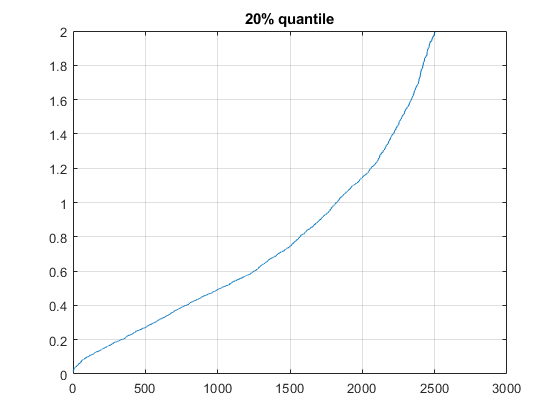

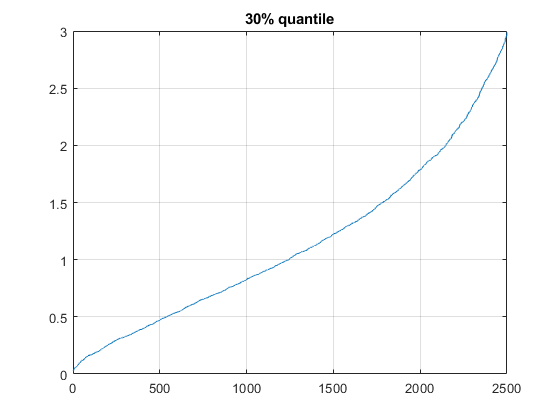

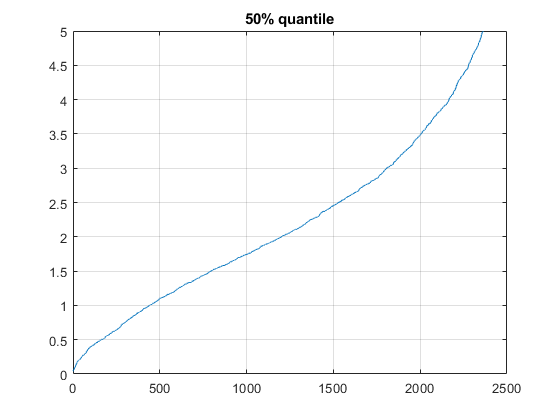

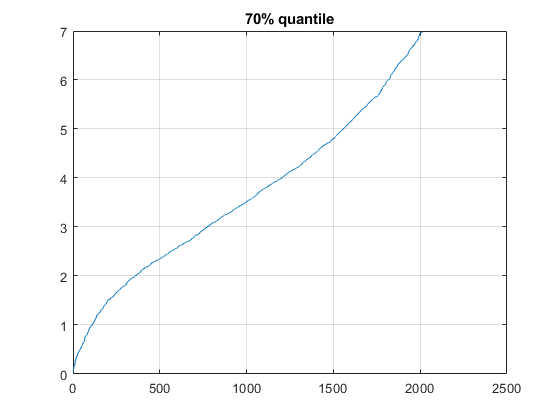

sz = size(dbData.equHFrtns.values);
aumClean.aumRet = NaN(sz);
aumClean.aum = dbData.aumTS;
aumClean.aum(aumClean.aum <=0) = NaN; % We do not want to divide by 0 to get "inf"!
for i = 2:sz(1)
    aumClean.aumRet(i,:) = aumClean.aum(i,:)./aumClean.aum(i-1,:)-1;
end % i

% Some funds report AUMs less often than every month. This effectively
% gives us periods of zero "aum returns". Taking these at face value will
% pollute our results. Eaisest is to just replace them with NaN (what we
% did). A more precise but laborious check would detect streams of zero AUM increases,
% take last AUM not equal today's, and use composite return from that
% period to recover one more data point for analysis. We stick with the
% 80/20 rule for now.
aumClean.aumRet(aumClean.aumRet==0) = NaN;

aumClean.aumDiff = (aumClean.aumRet - dbData.equHFrtns.values);
% For monthly returns over 1% use relative diff; under 1% abs. diff
%idxHighReturns = abs(dbData.equHFrtns.values)>0.01;
%aumClean.aumDiff(idxHighReturns) = aumClean.aumDiff(idxHighReturns)./sqrt(abs(dbData.equHFrtns.values(idxHighReturns))*100);
aumClean.aumDiff = aumClean.aumDiff*100;
aumClean.se = nanstd(aumClean.aumDiff);
aumQuantiles = [20 30 50 70];
for i=1:length(aumQuantiles)
  q = aumQuantiles(i);
  figure(i);
  z.fld = "abs" + string(q);
  z.data = prctile(abs(aumClean.aumDiff), q);
  aumClean.(z.fld) = z.data;
  z.data(z.data>q/10) = NaN;  % to highlight the appropriate segment on the graphs
  plot(1:length(z.data), sort(z.data'));
  grid;
  title(string(q) + "% quantile");
end % q

%cfgm.aumPass.perecntile = [20 30 50];
%cfgm.aumPass.passPct = [0.55 1.2 2 ];

The percentile of difference approach didn't go too well. (Was hoping to find a clear distinction between "well explained" and "poorly explained" AUMs. Instead got a very gradual overlap, and at levels too high to fit the bill.)

**Try another approach**: see how much of variation in AUMs we can explain by variation of cumulative returns.

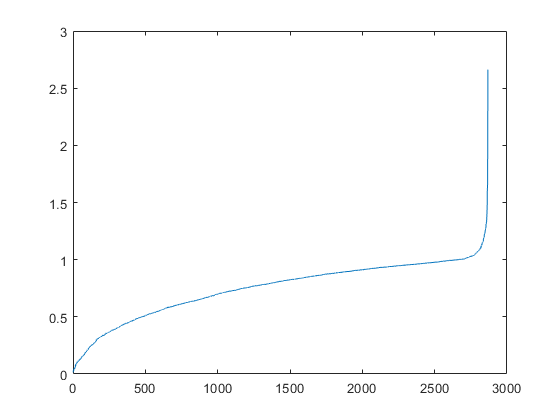

% calculate variations, and see what percentage of AUM variation is explained by returns
aumClean2.totVar = nansum(abs(aumClean.aumRet));
aumClean2.unexplainedVar = nansum(abs(aumClean.aumRet - dbData.equHFrtns.values));
aumClean2.pctUnexp = aumClean2.unexplainedVar ./ aumClean2.totVar;
aumClean2.var(1,:) = aumClean2.totVar;
aumClean2.var(2,:) = aumClean2.unexplainedVar;
aumClean2.var(3,:) = aumClean2.pctUnexp;
% plot(1:length(aumClean2.var(3,:)), sort(aumClean2.var(3,:)'));
aumClean2.uDiffs = sort(abs(aumClean.aumRet - dbData.equHFrtns.values));
aumClean2.uDiffLen = sum(~isnan(aumClean2.uDiffs));
% allow a few jumps in AUM (aiming to ignore very big jumps)
aumClean2.outlierStart = round(aumClean2.uDiffLen*0.9)+2;
aumClean2.varAdjustment = zeros(1, sz(2));
for j = 1:sz(2)
    aumClean2.varAdjustment(1,j) = sum(aumClean2.uDiffs(aumClean2.outlierStart(j):aumClean2.uDiffLen(j), j));
end % j
aumClean2.pctUnexpMod = (aumClean2.unexplainedVar - aumClean2.varAdjustment) ./ (aumClean2.totVar - aumClean2.varAdjustment);
aumClean2.var(4,:) = aumClean2.pctUnexpMod;
plot(sort(aumClean2.pctUnexpMod));

We will try different levels of AUM explained variations a few cells below.

This block of code prepares matlab table (regression input)

rDim = size(calc.rAlphaRtn_01mo);
rtnCnt = sum(~isnan(calc.rAlphaRtn_01mo),2);

tableSlices = cell(1,rDim(1)-3);
for i = 1:rDim(1)-3
    z.srcI = t0+i-1;
    z.retFltr = ~isnan(calc.rAlphaRtn_01mo(i, :)) ...
        & ~isnan(calc.rAlphaRtn_01mo(i+1, :)) & ~isnan(calc.rAlphaRtn_01mo(i+2, :)) ...
        & ~isnan(calc.rAlphaRtn_01mo(i+3, :));
            %& ~isnan(dbData.aumTS(z.srcI, :)) & (dbData.aumTS(z.srcI, :)>0);
    vec.Style = dbData.style.funds(z.retFltr);
    vec.GeoMand = dbData.geoMandate.funds(z.retFltr);
    % Update NaNs and zeroes to get a valid log output. We will have 0 in the log(x) for Any 0 or missing (NaN) AUMs 
    z.aum = dbData.aumTS(z.srcI, :);
    z.aum(isnan(z.aum)) = 0;
    z.aum(z.aum<0) = 0; 

    if cfgm.backFillAum
        if isfield(z, 'aumBf')
            z.prevAumBf = z.aumBf;
        end % if
        z.aumBf = z.aum;
        % Back-fill AUMs with prior month's figure, if available
        if i>2
            z.aumBf(z.aumBf==1) = z.prevAumBf(z.aumBf==1);
        end %i
        vec.LogAUMbf = log(z.aumBf(:,z.retFltr));
    end % if backfill
    vec.FundId = "i" + string(dbData.fundIdHeader(z.retFltr));
    %vec.FundId = dbData.fundIdHeader(z.retFltr);
    z.dt = dbData.equHFrtns.dates(z.srcI);
    %z.dtStr = "m" + datestr(z.dt, "yyyymm");
    %vec.YMo = repmat(z.dtStr, 1, sum(z.retFltr));
    
    z.YMo = str2double(datestr(z.dt, "yyyymm"));
    vec.YMo = repmat(z.YMo, 1, sum(z.retFltr));
    
    vec.LogAUM = log(z.aum(:,z.retFltr));
    
    horizons = [1 3 6 12 24 36 -1];
    alphaTags = ["p" "r"]; % primary and refined
    
    % pre-select commonly used variables (for a marginal speed improvement)
    for alp = alphaTags
        for h = horizons
            z.moStr = getMonthStr(h, "");
            z.moStrSrc = getMonthStr(h);
            z.(alp + "Rtn_" + z.moStr) = calc.(alp+"AlphaRtn_" + z.moStrSrc)(i, z.retFltr);
            if h>1 || h <=0
                z.(alp + "Vol_" + z.moStr) = calc.(alp+"AlphaVol_" + z.moStrSrc)(i, z.retFltr);
            end % if
        end % h
    end % alp
    
    for alp = alphaTags
        for iH = 1:length(horizons)
            z.moStr = getMonthStr(horizons(iH), "");
            % i2 >= i, always so i2 is used for vol, i for returns
            for iH2 = max(iH,2):length(horizons)
                z.moStr2 = getMonthStr(horizons(iH2), "");
                fld = alp + "SR_" + z.moStr;
                if iH ~= iH2
                    fld = fld + "r_" + z.moStr2 + "v";
                end
                vec.(fld) = z.(alp + "Rtn_" + z.moStr) ./ z.(alp + "Vol_" + z.moStr2);
            end % for i2
        end % for i
    end % alp

    predictionHorizons = [1 2 3];
    
    for alp = alphaTags
        for h = predictionHorizons
            vec.(alp+"NextSR" + string(h)) = calc.(alp+"AlphaRtn_01mo")(i+h, z.retFltr) ...
                ./ calc.(alp + "AlphaVol_12mo")(i+h, z.retFltr);
        end % h
    end % alp
    
    z.flds = fields(vec);
    z.tblSlice = table();

    for fld = string(z.flds)'
        z.fldVals = vec.(fld)';
        z.tblSlice = addvars(z.tblSlice, z.fldVals, 'NewVariableNames', fld);
    end % fld
    
    for fld = string(z.flds)'
        if class(z.tblSlice.(fld)) == "double"
            z.toDel = isnan(z.tblSlice.(fld));
            z.tblSlice = z.tblSlice(~z.toDel,:);
        end % if
    end % fld    
    tableSlices{i} = z.tblSlice;
end %for
clear i z vec; % clear variables "local" to the inside of the loop

thresholdYMo = 201900;
tblAll = vertcat(tableSlices{:});
tbl = tblAll(tblAll.YMo < thresholdYMo, :);
tblTestSeed = tblAll(tblAll.YMo >= thresholdYMo, :);
tbl.YMo = categorical(tbl.YMo);
clear tableSlices;

tblTestRes = tblTestSeed(:, "rNextSR1");
%tblTestAll = removevars(tblTestAll, ["NextSR"]);
tblTestAll =  addvars(tblTestSeed, tblTestSeed.YMo, 'NewVariableNames', "OrigYMo");
tblTestAll.YMo = repmat(min(tblAll.YMo), size(tblTestAll, 1), 1);
tblTestAll.YMo = categorical(tblTestAll.YMo);
tblTest = tblTestAll(tblTestAll.LogAUM>0,:);
tbl_1 = tbl(tbl.LogAUM>0,:); % remove missing AUMs
join(string(size(tbl_1)), " x ")

ans = "110766 x 65"

**ThIs is a VERY LONG calculation**. (2-3 hourrs) Recommended to skip these 2 cells.

Run batch of fixed effects regressions of type NextSR[1..3] ~ LogAUM + ReturnVar,

where ReturnVar are Sharpe ratios for returns and volatilities of horizons from 1mo to 36mo and full sample (~25 combinations). FIxed effects regression:

$\textit{y}_{it} = \alpha + \mathbf{\beta}'\mathbf\textit{x}_{it} + \mu_i +  \gamma_t  + \epsilon_{it}$; $\;\;\;i=1\ldotp \ldotp N,\;t=1\ldotp \ldotp T,\;\;\;\;\;$$\mu_0 \equiv0,  \gamma_0 \equiv0,  $ to avoid rank deficiency.

$\mu_i $,$\gamma_t $ are considered to be fixed, and $\epsilon_{it}$ is random.

cfgm.keepLMs = false; % this will consume A LOT of memory if turned on
for alp = alphaTags
    for h = predictionHorizons
        xVars = string(tbl_1.Properties.VariableNames(~cellfun(@isempty ...
            ,regexp(tbl_1.Properties.VariableNames, "^" + alp + "SR"))));
        for xVar = xVars
            lmSpec = alp + "NextSR" + string(h) +" ~ YMo + FundId + LogAUM + " + xVar;
            lm = fitlm(tbl_1, lmSpec);
            if cfgm.keepLMs lms.(alp).("m"+string(h)).(xVar) = lm; end
            lmRes.(alp).("m"+string(h)).(xVar).Coefficients = lm.Coefficients;
            lmRes.(alp).("m"+string(h)).(xVar).Rsquared = lm.Rsquared;
        end % col
    end % for h
end % for alp


% Gather results of individual regressions
for alp = alphaTags
    z.resAlp = [];
    for h = predictionHorizons
        z.resHorzn = [];
        z.hStr = string(h);
        z.lmR = lmRes.(alp).("m"+z.hStr);
        for col = string(fields(z.lmR))'
            z.res = z.lmR.(col).Coefficients(col,["Estimate", "pValue"]);
            z.res.Properties.VariableNames = ["Est_" + z.hStr "pVal_" + z.hStr];
            z.res.("Rsqr_" + z.hStr)(col) = z.lmR.(col).Rsquared.Adjusted;
            z.resHorzn = vertcat(z.resHorzn, z.res);
        end % col
        if isempty(z.resAlp)
            z.resAlp = z.resHorzn;
        else
            z.resAlp = [z.resAlp, z.resHorzn];
        end % if
    end % for h
    res.(alp + "Alp") = z.resAlp;
    res.(alp + "Alp") = sortrows(res.(alp + "Alp"), "Rsqr_1", "descend"); % we are assuming user will check pValues manually
end % for alp
clear z alp h col;

% write to Excel
writetable(res.pAlp, fullfile(outDataDir, "prmAlpRegr.csv"), 'WriteRowNames', true);
writetable(res.rAlp, fullfile(outDataDir, "rfnAlpRegr.csv"), 'WriteRowNames', true);

res.pAlp

ans = 27×9 table
                      Est_1      pVal_1    Rsqr_1      Est_2      pVal_2    Rsqr_2      Est_3      pVal_3    Rsqr_3 
                     ________    ______    _______    ________    ______    _______    ________    ______    _______

    pSR_12           0.045629      0        0.3934    0.040212      0       0.37932    0.034521      0       0.36668
    pSR_06r_12v      0.035068      0       0.38518     0.02945      0       0.37049    0.025626      0       0.36057
    pSR_24           0.050916      0       0.38128    0.046208      0       0.37119    0.042078      0       0.36288
    pSR_12r_24v      0.

res.rAlp

ans = 27×9 table
                      Est_1      pVal_1    Rsqr_1      Est_2      pVal_2    Rsqr_2      Est_3      pVal_3    Rsqr_3 
                     ________    ______    _______    ________    ______    _______    ________    ______    _______

    rSR_12           0.047891      0       0.40237    0.042562      0       0.38713    0.036097      0       0.37158
    rSR_06r_12v      0.037206      0       0.39244    0.032043      0       0.37726    0.027555      0       0.36496
    rSR_24           0.055454      0       0.39112    0.050405      0       0.37949     0.04533      0       0.36887
    rSR_Full         0.

Split AUM variable into sub-variables based on fraction of "explainability" with returns.

thresholds = [10 20 30 60 80 90 100];
oldTh = 0;
idxAll = zeros(height(tbl_1),1);
for th = thresholds
    idx = zeros(height(tbl_1),1);
    for fId = dbData.fundIdHeader(aumClean2.pctUnexpMod<th/100 & aumClean2.pctUnexpMod >= oldTh/100)
        idx = idx | tbl_1.FundId == "i" + string(fId);
    end
    z.var = "LogAUMvar" + string(th);
    tbl_1.(z.var) = zeros(height(tbl_1),1);
    tbl_1.(z.var)(idx) = tbl_1.LogAUM(idx);
    oldTh = th;
    idxAll = idxAll | idx;
end % th    
tbl_1.LogAUMvarRest = zeros(height(tbl_1),1);
tbl_1.LogAUMvarRest(~idxAll) = tbl_1.LogAUM(~idxAll);


### A fixed effects regression (old section)

lm0 = fitlm(tbl_1, "pNextSR1 ~ YMo + FundId + LogAUM + pSR_12");
lm0.Rsquared.Adjusted

ans = 0.3934

filterLmCoeffs(lm0, "^(YMo|FundId)[_]")

ans = 3×4 table
                   Estimate        SE         tStat       pValue   
                   ________    __________    _______    ___________

    (Intercept)     0.67144      0.042873     15.661     3.1994e-55
    LogAUM         -0.03628     0.0016001    -22.674    1.5008e-113
    pSR_12         0.045629    0.00053196     85.775              0


- Residuals on the pSR_12 variable don't look too random (graph 2)?

- Where do pSR_12 of up to 100 come from (graph 3; esp. given that pNextSR1 is always under 10)? 

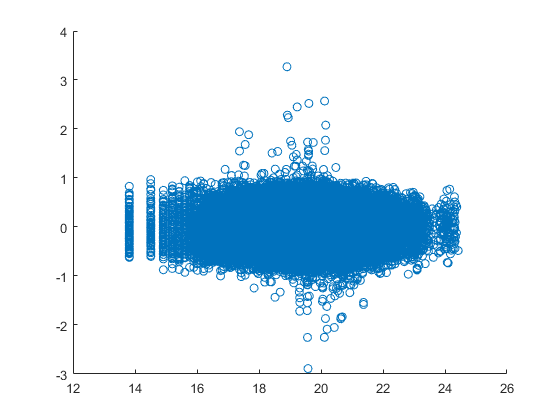

scatter(lm0.Variables.LogAUM, lm0.Residuals.Raw)

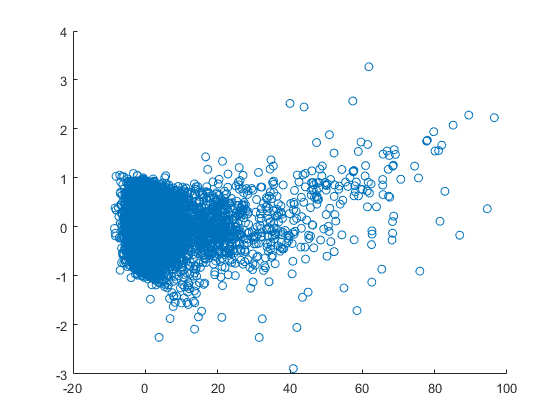

scatter(lm0.Variables.pSR_12, lm0.Residuals.Raw)

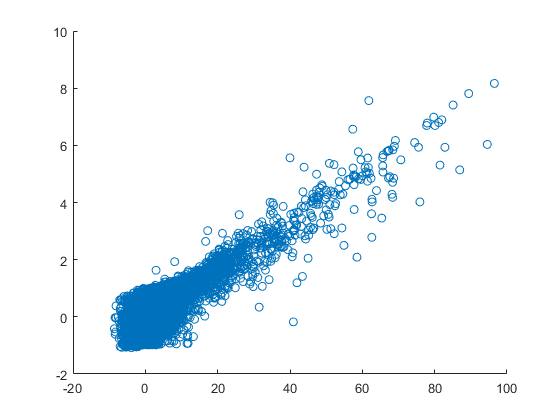

scatter(lm0.Variables.pSR_12, lm0.Variables.pNextSR1)

see how AUMs of different "cleanliness" (% of unexplained AUM variation with respect to returns) fare in regression.

We see a decreasing slope (beta) with unexplained variation increase (the number in LogAUMvar**NN**). We also see noticeably bigger p-value when NN>=100 (returns explain 0 of AUM variation). So "cleaner" Aums have 

A slight increase in adjusted R-squared compared to base model also suggests that our separation of AUMs into these categories is woth it.

Histograms below also show that our categories of AUMs fall in the same range of e^19..e^20 ($65-180MM), so the slope difference is not due to non-linearity (of AUM to expected returns dependency).

lm = fitlm(tbl_1, "pNextSR1 ~ YMo + FundId "...

ans = 10×4 table
                     Estimate         SE         tStat       pValue  
                     _________    __________    _______    __________

    (Intercept)        0.62798      0.065107     9.6453     5.252e-22
    pSR_12             0.04557    0.00053348      85.42             0
    LogAUMvar10      -0.086112      0.021937    -3.9254    8.6657e-05
    LogAUMvar20      -0.072211      0.013754    -5.2502    1.5223e-07
    LogAUMvar30      -0.069477      0.011329     -6.133    8.6551e-10
    LogAUMvar60      -0.033685      0.003352    -10.049    9.4822e-24
    LogAUMvar80      -0.029725     0.0030193    -9.8448    7.3807e-23
    LogAUMvar90      -0.047591     0.0036589    -13.007     1.192e-38
    

    + "+ LogAUMvar10 + LogAUMvar20 + LogAUMvar30 + LogAUMvar60 + LogAUMvar80 " ...

ans = 0.3936

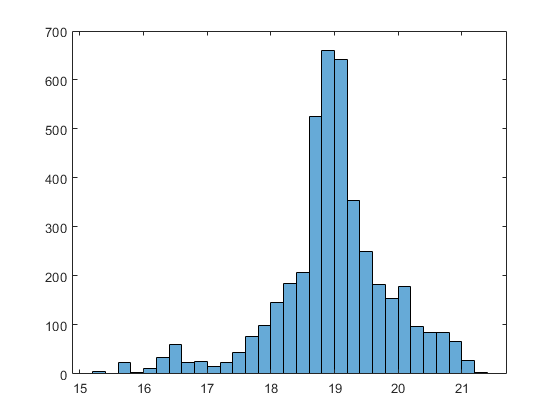

    + "+ LogAUMvar90 + LogAUMvar100 + LogAUMvarRest + pSR_12");

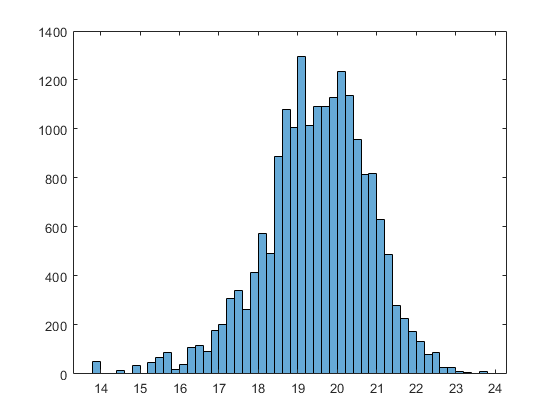

% Regression results less year-month dummy variables

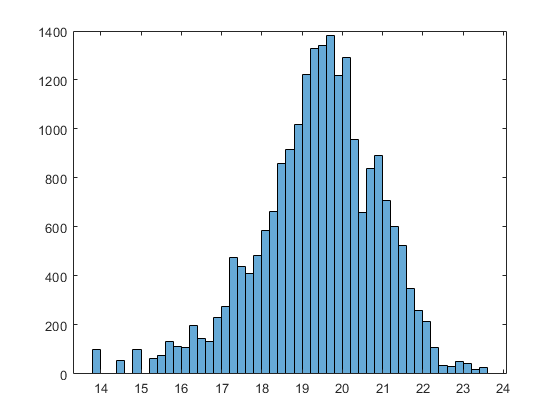

filterLmCoeffs(lm, "^(YMo|FundId)[_]")

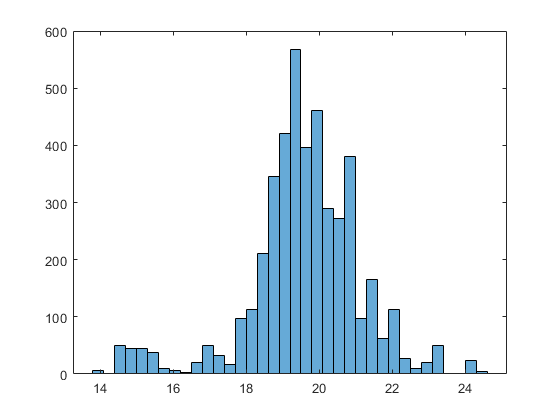

lm.Rsquared.Adjusted

histogram(nonzeros((tbl_1.LogAUMvar10 + tbl_1.LogAUMvar20)'));
histogram(nonzeros((tbl_1.LogAUMvar90)'));
histogram(nonzeros((tbl_1.LogAUMvar100)'));
histogram(nonzeros((tbl_1.LogAUMvarRest)'));

Remove fixed effects within each year and fund, and look at correlations of full vector:

(This is for the raw data in the matrix form)

i=1;
mDm=[];
calcFldNames = string(fieldnames(calc));
for fld=calcFldNames'
    z.mean_2= nanmean(calc.(fld), 2);
    z.mean_1 = nanmean(calc.(fld), 1);
    z.mean_all = nanmean(calc.(fld), 'all');
    calcDm.(fld) = calc.(fld) - z.mean_2 - z.mean_1 + z.mean_all;
    mDm(:,i) = calcDm.(fld)(:)';
    i = i+1;
end
clear z;
R=corrcoef(mDm, 'Rows', 'pairwise');
rTbl = array2table(R, "RowNames", calcFldNames,"VariableNames", calcFldNames)

rTbl = 38×38 table
                      rAlphaRtn_01mo    pAlphaRtn_01mo    rAlphaRtn_Full    rAlphaVol_Full    rAlphaSrp_Full    pAlphaRtn_Full    pAlphaVol_Full    pAlphaSrp_Full    rAlphaRtn_36mo    rAlphaVol_36mo    rAlphaSrp_36mo    pAlphaRtn_36mo    pAlphaVol_36mo    pAlphaSrp_36mo    rAlphaRtn_24mo    rAlphaVol_24mo    rAlphaSrp_24mo    pAlphaRtn_24mo    pAlphaVol_24mo    pAlphaSrp_24mo    rAlphaRtn_12mo    rAlphaVol_12mo    rAlphaSrp_12mo    pAlphaRtn_12mo    pAlphaVol_12mo    pAlphaSrp_12mo    rAlphaRtn_06mo    rAlpha

Returns/Sharpes don't appear highly correlated (~0.3), but primary and refined alpha returns and vols for same horizons do (97%-99%)

Now look at correlations for the factors selected for regression.

We also removed fixed effects: $\tilde\mathbf\textit{x}_{it} = \mathbf\textit{x}_{it} - \mathbf\bar\textit{x}_{i*} - \mathbf\bar\textit{x}_{*t} + \mathbf\bar\textit{x}_{**}$

tbl_1_reFE = tbl_1;
tbl_1_reFE.FundId = categorical(tbl_1_reFE.FundId);
tbl_1_reFE = removeFixedEffects(tbl_1_reFE, ["FundId", "YMo"]);

R=corrcoef(table2array(tbl_1_reFE), 'Rows', 'pairwise');
rTbl = array2table(R, "RowNames", tbl_1_reFE.Properties.VariableNames,"VariableNames", tbl_1_reFE.Properties.VariableNames)

rTbl = 61×61 table
                      LogAUM      pSR_01r_03v    pSR_01r_06v    pSR_01r_12v    pSR_01r_24v    pSR_01r_36v    pSR_01r_Fullv     pSR_03      pSR_03r_06v    pSR_03r_12v    pSR_03r_24v    pSR_03r_36v    pSR_03r_Fullv     pSR_06      pSR_06r_12v    pSR_06r_24v    pSR_06r_36v    pSR_06r_Fullv      pSR_12       pSR_12r_24v    pSR_12r_36v    pSR_12r_Fullv     pSR_24     pSR_24r_36v    pSR_24r_Fullv    pSR_36     pSR_36r_Fullv    pSR_Full    rSR_01r_03v    rSR_01r_06v    

Same correlation matrix without fixed effects removed (no specific point; just for reference)

R3=corrcoef(table2array(tbl_1(:, tbl_1_reFE.Properties.VariableNames)), 'Rows', 'pairwise');
array2table(R3, "RowNames", tbl_1_reFE.Properties.VariableNames,"VariableNames", tbl_1_reFE.Properties.VariableNames)

**Unfinished**

See if we can predict anything with that. We use the fact that Matlab implementation seems to set $ \gamma_0 \equiv0,  $ in line with our spec, so we replace the YMo variable with the minimum year-month to get zero intercept specific to the time period.

(with R_3, V_12, SR_36 removed)

lmP = fitlm(tbl_1, "NextSR ~ YMo + FundId + LogAUM + SR_1r_12v + SR_3r_12v + R_3 + SR_12 + SR_Tot");
sa = grpstats(tblTest, "OrigYMo", "mean", "DataVars", ["NextSR"]);

tblTest.NextSRdm = tblTest.NextSR;
for ym = sa.OrigYMo'
    tblTest.NextSRdm(tblTest.OrigYMo == ym) ...
        = tblTest.NextSR(tblTest.OrigYMo == ym) - sa.mean_NextSR(sa.OrigYMo ==ym);
end % for ym

tblTest.NextSRdmAbs = abs(tblTest.NextSR);
bench = grpstats(tblTest, "OrigYMo", "mean", "DataVars", ["NextSRdmAbs"]);
prd = lmP.predict(tblTest);

save(fullfile(inDataDir, ensureFileExt(fnCache + "_o", "mat")), 'res', 'lmRes');
